# Goal of the assignment: to do data pre-processing

in order to be able to feed the pre-processed data onto a NLP neural network

clc; clear all; close all; 

## Import data

filename = "sonnets.txt";
textData = extractFileText(filename);

## Tokenize data

documents = tokenizedDocument(textData);
rawBag    = bagOfWords(documents)

rawBag =   bagOfWords with properties:

          Counts: [2 1 2 1 1 1 1 1 1 524 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 2 345 1 5 2 14 10 4 1626 82 2 17 6 25 14 10 89 81 363 2 44 78 40 3 3 7 3 11 104 8 155 210 2 331 40 30 11 52 1 240 1 3 163 1 1 7 146 1 31 4 12 3 1 50 9 17 8 … ] (1×3691 double)
      Vocabulary: ["SONNETS"    "TO"    "THE"    "ONLY"    "BEGETTER"    "OF"    "THESE"    "INSUING"    "MR"    "."    "W"    "H"    "ALL"    "HAPPINESS"    "AND"    "THAT"    "ETERNITY"    "PROMISED"    "BY"    "OUR"    …    ] (1×3691 string)
        NumWords: 3691
    NumDocuments: 1


## Remove stop words

Note: modern NLP models do not need this step

documents = addPartOfSpeechDetails(documents); % This helps the removal of stop words.
documents = removeStopWords(documents);
documents = normalizeWords(documents,'Style','lemma');
documents = erasePunctuation(documents);
documents = removeShortWords(documents,2);
documents = removeLongWords(documents,15);
afterBag  = bagOfWords(documents)

afterBag =   bagOfWords with properties:

          Counts: [1 1 1 1 1 4 2 1 7 1 1 1 1 8 52 3 14 5 2 74 11 26 15 16 3 78 3 8 3 26 8 235 2 44 30 11 94 1 266 1 3 1 80 1 4 28 21 4 65 10 8 53 32 8 6 1 1 6 6 1 6 2 2 9 1 10 6 1 3 6 5 162 1 10 59 1 9 1 8 1 1 16 15 1 3 2 7 2 21 20 1 … ] (1×2584 double)
      Vocabulary: ["sonnets"    "begetter"    "insuing"    "sonnet"    "happiness"    "eternity"    "promise"    "everliving"    "poet"    "wisheth"    "wellwishing"    "adventurer"    "setting"    "forth"    "fair"    …    ] (1×2584 string)
        NumWords: 2584
    NumDocuments: 1


## Statistics on the preprocessing

Bags of words and n-grams

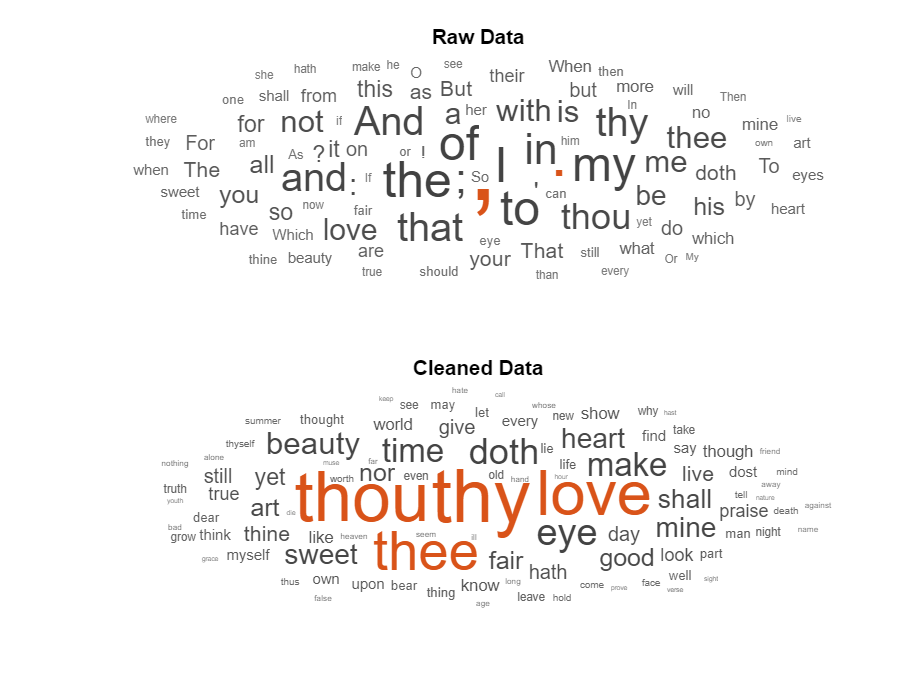

figure;
nexttile;
wordcloud(rawBag);
title("Raw Data")

nexttile;
wordcloud(afterBag);
title("Cleaned Data")

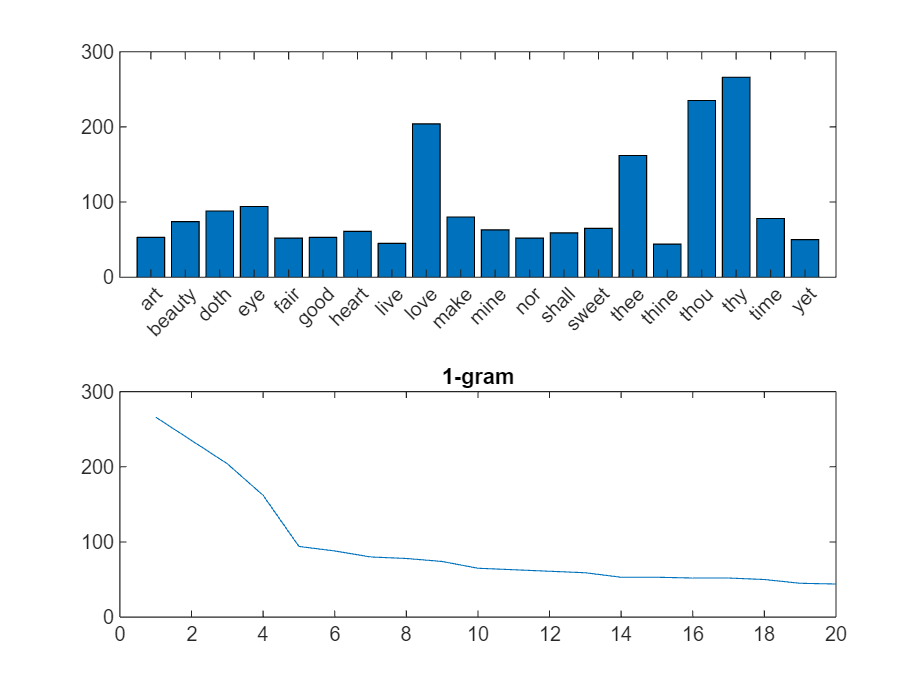

tblWords = topkwords(afterBag, 20);

figure; 
nexttile;
bar(categorical(tblWords.Word), tblWords.Count);

nexttile;
plot(tblWords.Count);
title("1-gram");

## N-gram analysis

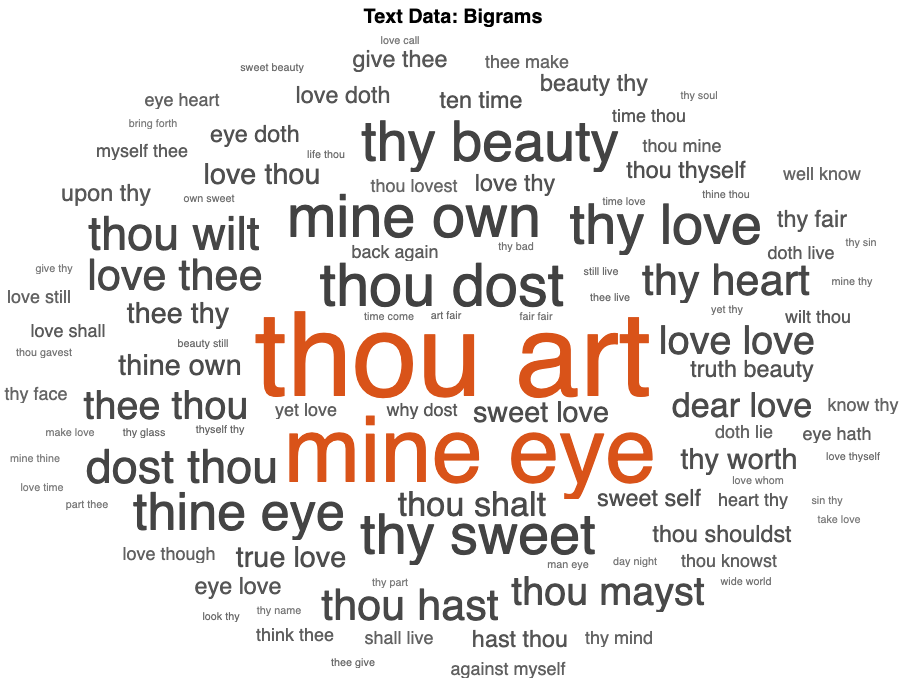

bag = bagOfNgrams(documents, NGramLengths=2);
figure
wordcloud(bag);
title("Text Data: Bigrams")

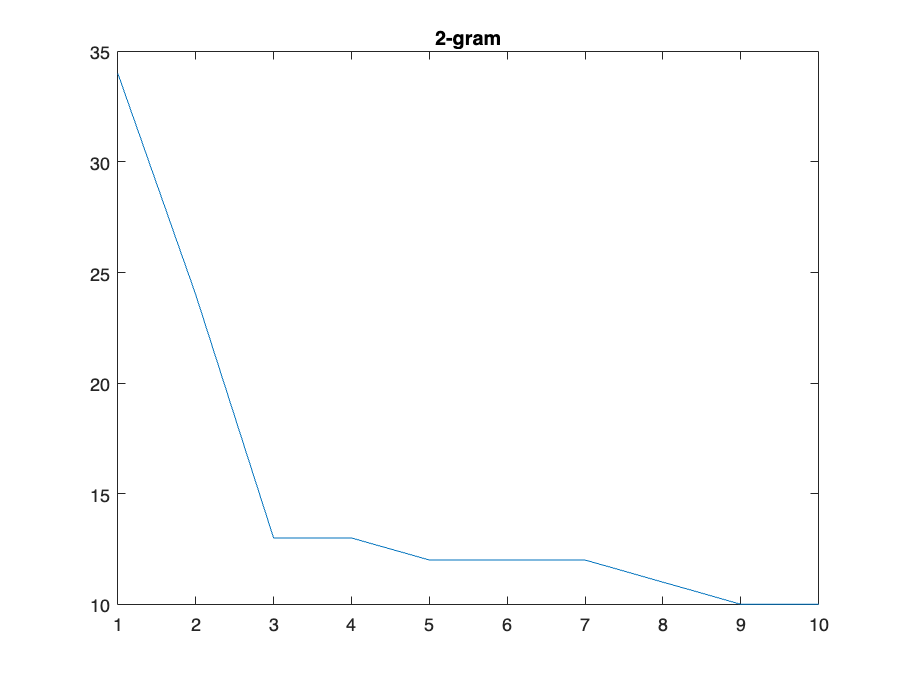


tblWords = topkngrams(bag, 10);

figure; 
plot(tblWords.Count);
title("2-gram");

## Converting documents into sequences

textData = replace(textData,"  ","");
textData = split(textData,[newline newline]); % Split the text into separate sonnets
textData = textData(5:2:end);

textData

textData = 154×1 string array
    "FROM fairest creatures we desire increase,↵That thereby beauty's rose might never die,↵But as the riper should by time decease,↵His tender heir might bear his memory:↵But thou, contracted to thine own bright eyes,↵Feed'st thy light'st flame with self-substantial fuel,↵Making a famine where abundance lies,↵Thyself thy foe, to thy sweet self too cruel.↵Thou that art now the world's fresh ornament↵And only herald to the gaudy spring,↵Within thine own bud buriest thy content↵And, tender churl, makest waste in niggarding.↵Pity the world, or else this glutton be,↵To eat the world's due, by the grave and thee."
    "When forty winters shall beseige thy brow,↵And dig deep trenches in thy beauty's field,↵Thy youth's proud livery, so gazed on now,↵Will be a tatter'd weed, of small worth held:↵Then being ask'd where all thy beauty lies,↵Where all the treasure of thy lusty days,↵To say, within thine own deep-sunken eyes,↵Were an all-eating shame and thriftless pr

## Sequences of vectors for the predictors and categorical sequences for responses

Create special characters to denote "start of text", "whitespace", "end of text" and "newline". Use the special characters `"\x0002"` (start of text), `"\x00B7"` ("·", middle dot), `"\x2403"` ("␃", end of text), and `"\x00B6"` ("`¶`", pilcrow) respectively. To prevent ambiguity, you must choose special characters that do not appear in the text. Because these characters do not appear in the training data, they can be used for this purpose.

startOfTextCharacter    = compose("\x0002");
whitespaceCharacter     = compose("\x00B7");
endOfTextCharacter      = compose("\x2403");
newlineCharacter        = compose("\x00B6");


## Processing the data

so we can use them as inputs in a NN. 


textData            = startOfTextCharacter + textData;
textData            = replace(textData,[" " newline],[whitespaceCharacter newlineCharacter]);
uniqueCharacters    = unique([textData{:}]);
numUniqueCharacters = numel(uniqueCharacters);
numDocuments        = numel(textData);
XTrain              = cell(1,numDocuments);
YTrain              = cell(1,numDocuments);

for i = 1:numel(textData)
    characters      = textData{i};
    sequenceLength  = numel(characters);
    
    % indices of characters
    [~,idx] = ismember(characters,uniqueCharacters);
    
    % characters to vectors
    X = zeros(numUniqueCharacters,sequenceLength);
    for j = 1:sequenceLength
        X(idx(j),j) = 1;
    end
    
    % vector of categorical responses with end of text character
    charactersShifted = [cellstr(characters(2:end)')' endOfTextCharacter];
    Y = categorical(charactersShifted);
    
    XTrain{i} = X;
    YTrain{i} = Y;
end

textData{1}

ans = '□FROM·fairest·creatures·we·desire·increase,¶That·thereby·beauty's·rose·might·never·die,¶But·as·the·riper·should·by·time·decease,¶His·tender·heir·might·bear·his·memory:¶But·thou,·contracted·to·thine·own·bright·eyes,¶Feed'st·thy·light'st·flame·with·self-substantial·fuel,¶Making·a·famine·where·abundance·lies,¶Thyself·thy·foe,·to·thy·sweet·self·too·cruel.¶Thou·that·art·now·the·world's·fresh·ornament¶And·only·herald·to·the·gaudy·spring,¶Within·thine·own·bud·buriest·thy·content¶And,·tender·churl,·makest·waste·in·niggarding.¶Pity·the·world,·or·else·this·glutton·be,¶To·eat·the·world's·due,·by·the·grave·and·thee.'

YTrain{1}

ans = 1×611 categorical array
     F      R      O      M      ·      f      a      i      r      e      s      t      ·      c      r      e      a      t      u      r      e      s      ·      w      e      ·      d      e      s      i      r      e      ·      i      n      c      r      e      a      s      e      ,      ¶      T      h      a      t      ·      t      h      e      r      e      b      y      ·      b      e      a      u      t      y            s      ·      r      o      s      e      ·      m      i      g      h      t      ·      n      e      v      e      r      ·      d      i      e      ,      ¶      B      u      t      ·      a      s      ·      t      h      e      ·      r      i      p      e      r      ·      s      h      o      u      l      d      ·      b      y      ·      t      i      m      e      ·      d      e      c      e      a      s      e      ,      ¶      H      i      s      ·      t      e      n      d      e      r      